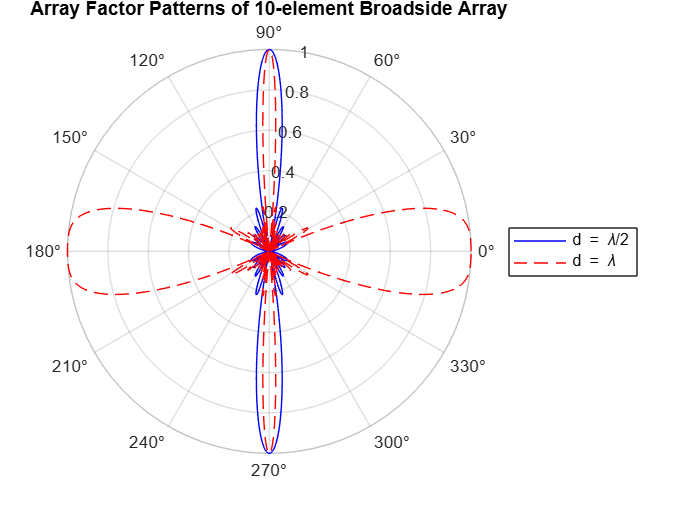

clc;
clear;

% Parameters
N = 10;                      % Number of elements
theta = linspace(0, 2*pi, 1000);   % Angle from 0 to 2π
lambda = 1;                 % Wavelength (normalize to 1)
k = 2*pi/lambda;            % Wave number
beta = 0;                   % Broadside (β = 0)

% Case 1: d = λ/2
d1 = lambda/2;
psi1 = k*d1*cos(theta) + beta;
AF1 = abs(sin(N*psi1/2)./(N*sin(psi1/2)));  % Array Factor
AF1 = AF1 / max(AF1);  % Normalize

% Case 2: d = λ
d2 = lambda;
psi2 = k*d2*cos(theta) + beta;
AF2 = abs(sin(N*psi2/2)./(N*sin(psi2/2)));
AF2 = AF2 / max(AF2);  % Normalize

% Plotting
figure;
polarplot(theta, AF1, 'b', 'DisplayName', 'd = \lambda/2');
hold on;
polarplot(theta, AF2, 'r--', 'DisplayName', 'd = \lambda');
title('Array Factor Patterns of 10-element Broadside Array');
legend;


% Optional: FNBW and Directivity approximations
% FNBW for broadside array: approx = 2*lambda / (N*d)
FNBW1 = 2*lambda / (N*d1);
FNBW2 = 2*lambda / (N*d2);
disp(['FNBW (d = λ/2): ', num2str(FNBW1), ' radians']);

FNBW (d = λ/2): 0.4 radians


disp(['FNBW (d = λ): ', num2str(FNBW2), ' radians']);

FNBW (d = λ): 0.2 radians



% Directivity approximation for uniform linear array
D1 = 2*N;   % Approximation
disp(['Approximate Directivity (N=10): ', num2str(D1), ' or ', num2str(10*log10(D1)), ' dB']);

Approximate Directivity (N=10): 20 or 13.0103 dB
